# Local Planner Simulation

## function import

addpath("utils/env/", "utils/data/map/", "utils/plot/", "utils/animation/");
addpath("local_planner/");
addpath("global_planner/graph_search/");
addpath("global_planner/sample_search/");
addpath(genpath("utils/"), genpath("global_planner/"));

## initialize

clear all;
clc;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% start and goal pose
start = [3, 2, 0];
goal = [18, 29, pi / 2];

% planner
% global_planner_name = "a_star";
% global_planner_name = "dijkstra";
global_planner_name = "voronoi_plan";

% local_planner_name = "pid_plan";
local_planner_name = "dwa_plan";
% local_planner_name = "apf_plan";
% local_planner_name = "rpp_plan";
% local_planner_name = "lqr_plan";
% local_planner_name = "mpc_plan";

## Path planning

global_planner = str2func(global_planner_name);
[path, global_flag, cost, expand] = global_planner(grid_map, start(:, 1:2), goal(:, 1:2));

## trajectory planning

local_planner = str2func(local_planner_name);
[pose, traj, local_flag] = local_planner(start, goal, "path", path, "map", grid_map);

goal arrived!


## visualization

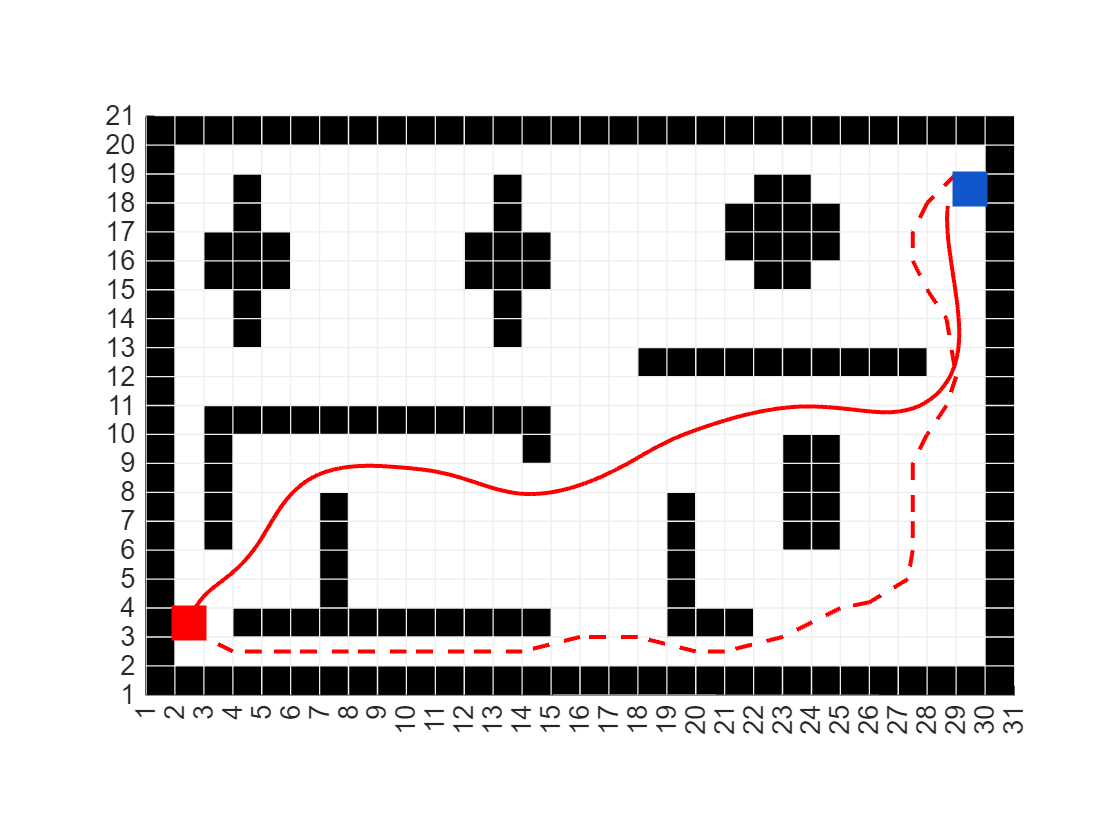

clf;
hold on

% plot grid map
plot_grid(grid_map);
plot_path(path, G);

% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");

% animation
% record_video = true;
% animation(local_planner_name, pose, traj, G / 2, record_video);
plot_path(pose, G);
hold off